f = @(t,y) - y;
t0 = 0;
tf = 10;
h = 0.1;
y0 = 1;
%[t1,y1]= milne(f,y0,t0,tf,h);
%plot(t1,y1)
%hold on

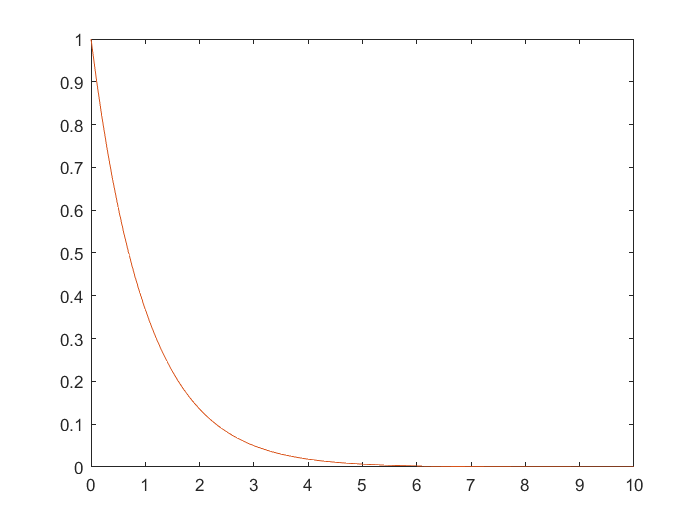

[t2,y2] = odeABM4(f,y0,t0,tf,h);
plot(t2,y2)

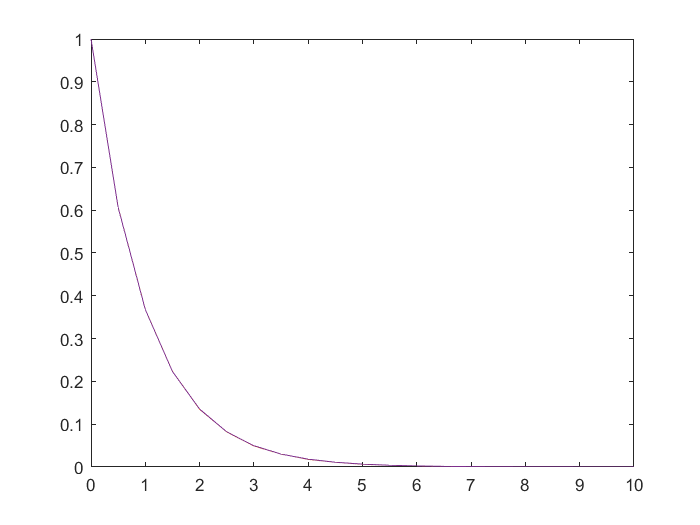

syms y(x)
eqn = diff(y,x) == -y;
cond = y(0) ==1;
yp = dsolve(eqn,cond);
x = 0:h:10;
fa = matlabFunction(yp);
plot(x,fa(x));

## Método de euler implícito

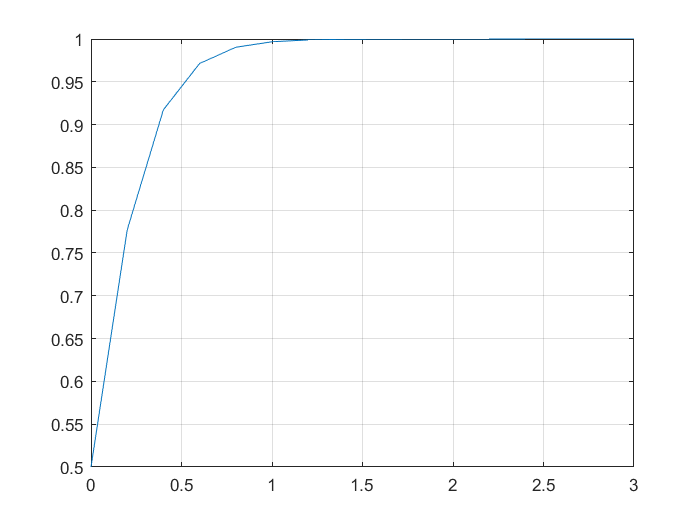

f = @(t,y) y+8*y^2-9*y^3;
y0 = 0.5;
t0 = 0;
tf = 3;
h = 0.20;
[t,y] = odeImplicitEuler(f,y0,t0,tf,h);
plot(t,y);
hold on
grid on

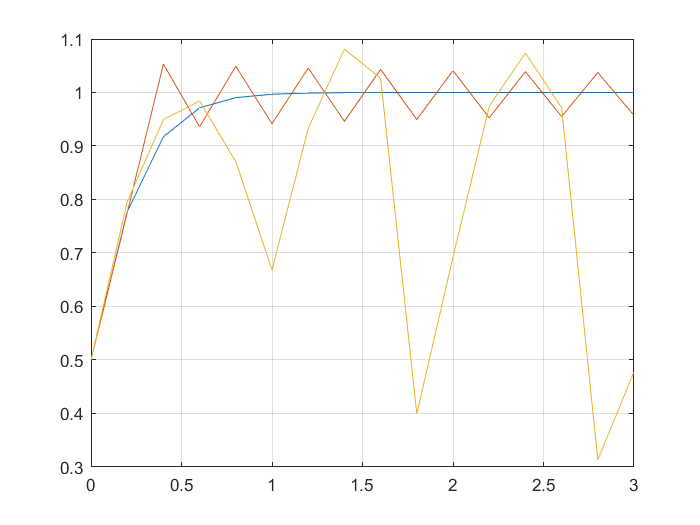

[t2,y2] = odeEuler(f,y0,t0,tf,h);
plot(t2,y2);

[t3,y3] = odeABM4(f,y0,t0,tf,h);
plot(t3,y3);
hold off